1. 将某个病人的检验结果带入两个正态分布中计算似然，如果p(x|w_1)的概率大，那就决策为健康，如果p(x|w_2) 的概率大，那就决策为感染.

mu = [0,1],sigma = [0.3,0.1];

mu =      0     1


x= 0.0;
cls = desision(x,mu,sigma); %决策函数
if(cls)
    sprintf('异常')
else
    sprintf('正常')
end

ans = '正常'

第二题，直接计算后验概率

T = 0:0.01:2; %枚举T的值，设定求解范围和求解步长
P_I = 0.0001; %感染的概率
P_I_x_1 = zeros(1,length(T))

P_I_x_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


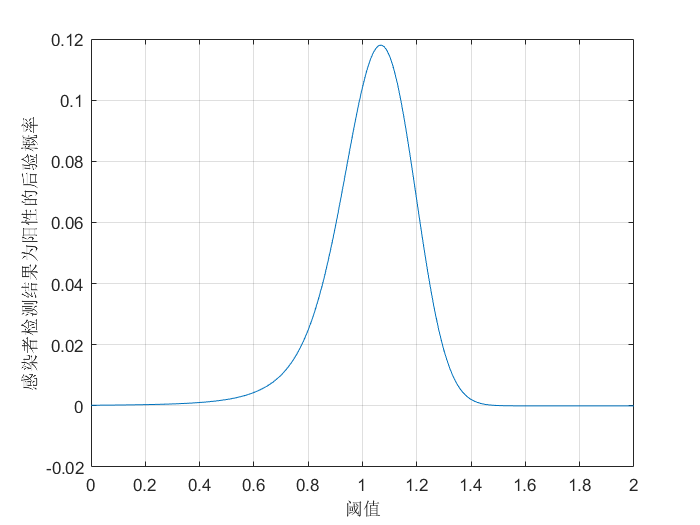

for i=1:length(T) %
    P_I_x_1(i) = (1-cdf('I', T(i))).*P_I./((1-cdf('I', T(i))).*P_I + (1-cdf('H', T(i))).*(1-P_I)); %报告中的公式4
end
plot(T, P_I_x_1);
xlabel('阈值')
ylabel('感染者检测结果为阳性的后验概率')
grid on;

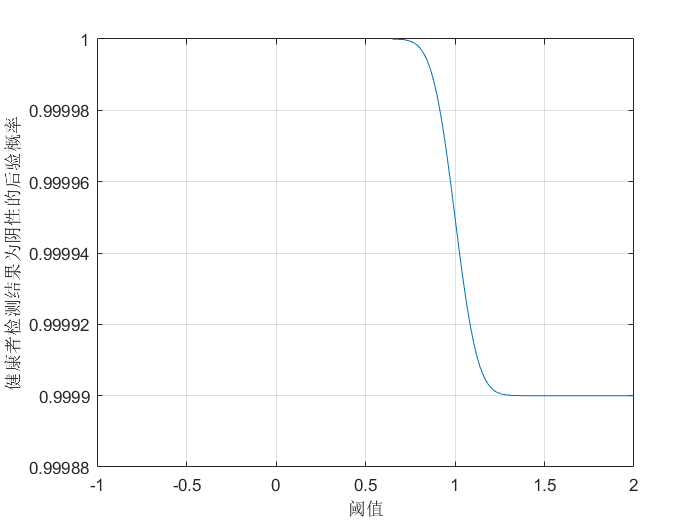

T=-1:0.01:2;
P_H_x_0 = zeros(1,length(T));
for i=1:length(T)
    P_H_x_0(i) = (cdf('H', T(i))).*(1-P_I);
    temp = P_H_x_0(i) + (cdf('I', T(i))).*(P_I);
    P_H_x_0(i)=P_H_x_0(i)/temp; %报告中的公式5
end
plot(T, P_H_x_0);
xlabel('阈值')
ylabel('健康者检测结果为阴性的后验概率')
grid on;

本小题仍然是确定阈值，同样我们将其设为T。我们根据后验概率来计算期望风险。

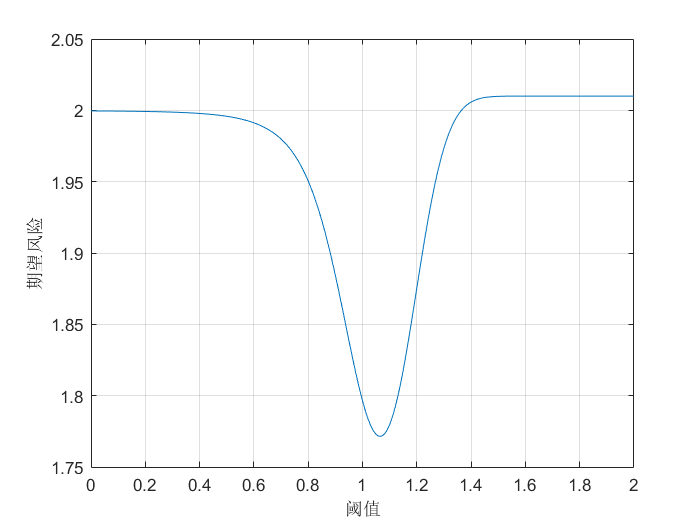

T = 0:0.01:2;
P_I = 0.0001;
P_I_x_0 = zeros(1,length(T));
for i=1:length(T)
    P_I_x_0(i) = (cdf('I', T(i))).*P_I./((cdf('I', T(i))).*P_I + (cdf('H', T(i))).*(1-P_I));
end
P_H_x_1 = zeros(1,length(T));
for i=1:length(T)
    P_H_x_1(i) = (1-cdf('H', T(i))).*(1-P_I);
    temp = P_H_x_1(i) + (1-cdf('I', T(i))).*(P_I);
    P_H_x_1(i)=P_H_x_1(i)/temp;
end
R_t = 2 * P_H_x_1 + 100 * P_I_x_0; %计算得到期望风险
plot(T,R_t);
xlabel('阈值')
ylabel('期望风险')
grid on;

function [cls,f0,f1] = desision(x,mu,sigma)
    f0 = 1/(sqrt(2*pi)*sigma(1))*exp(-(x-mu(1))^2/(2*sigma(1)^2));
    f1 = 1/(sqrt(2*pi)*sigma(2))*exp(-(x-mu(2))^2/(2*sigma(2)^2));
    if(f0>f1)
        cls = 0;
    else
        cls = 1;
    end
end
function prob = cdf(type, T)
    x=-10:0.01:T;
    if(type == 'I')
        y=normpdf(x,1,0.1);
    else
        y=normpdf(x,0,0.3);
    end
    prob = trapz(y)*0.01;
end